# Speech Command Recognition Using Deep Learning

## Load Speech Commands Data Set

downloadFolder = matlab.internal.examples.downloadSupportFile("audio","google_speech.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
dataset = fullfile(dataFolder,"google_speech");

## Create Training Datastore

ads = audioDatastore(fullfile(dataset,"train"), ...
    IncludeSubfolders=true, ...
    FileExtensions=".wav", ...
    LabelSource="foldernames")

ads =   audioDatastore with properties:

                       Files: {
                              '/tmp/google_speech/train/bed/00176480_nohash_0.wav';
                              '/tmp/google_speech/train/bed/004ae714_nohash_0.wav';
                              '/tmp/google_speech/train/bed/004ae714_nohash_1.wav'
                               ... and 51085 more
                              }
                     Folders: {
                              '/tmp/google_speech/train'
                              }
                      Labels: [bed; bed; bed ... and 51085 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


## Choose Words to Recognize

commands = categorical(["up","down","left","right","stop","go"]);

isCommand = ismember(ads.Labels,commands);
isUnknown = ~isCommand;

includeFraction = 0.1;
mask = rand(numel(ads.Labels),1) < includeFraction;
isUnknown = isUnknown & mask;
ads.Labels(isUnknown) = categorical("unknown");

adsTrain = subset(ads,isCommand|isUnknown);
countEachLabel(adsTrain)

ans = 7×2 table
     Label     Count
    _______    _____

    down       1842 
    go         1861 
    left       1839 
    right      1852 
    stop       1885 
    unknown    4049 
    up         1843 


## Create Validation Datastore

ads = audioDatastore(fullfile(dataset,"validation"), ...
    IncludeSubfolders=true, ...
    FileExtensions=".wav", ...
    LabelSource="foldernames")

ads =   audioDatastore with properties:

                       Files: {
                              '/tmp/google_speech/validation/bed/026290a7_nohash_0.wav';
                              '/tmp/google_speech/validation/bed/060cd039_nohash_0.wav';
                              '/tmp/google_speech/validation/bed/060cd039_nohash_1.wav'
                               ... and 6795 more
                              }
                     Folders: {
                              '/tmp/google_speech/validation'
                              }
                      Labels: [bed; bed; bed ... and 6795 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


isCommand = ismember(ads.Labels,commands);
isUnknown = ~isCommand;

includeFraction = 0.1;
mask = rand(numel(ads.Labels),1) < includeFraction;
isUnknown = isUnknown & mask;
ads.Labels(isUnknown) = categorical("unknown");

adsValidation = subset(ads,isCommand|isUnknown);
countEachLabel(adsValidation)

ans = 7×2 table
     Label     Count
    _______    _____

    down        264 
    go          260 
    left        247 
    right       256 
    stop        246 
    unknown     539 
    up          260 


## Compute Auditory Spectrograms

To prepare the data for efficient training of a convolutional neural network, convert the speech waveforms to auditory-based spectrograms.

Define the parameters of the feature extraction. `segmentDuration` is the duration of each speech clip (in seconds). `frameDuration` is the duration of each frame for spectrum calculation. `hopDuration` is the time step between each spectrum. `numBands` is the number of filters in the auditory spectrogram.

fs = 16e3; % Known sample rate of the data set.

segmentDuration = 1;
frameDuration = 0.025;
hopDuration = 0.010;

segmentSamples = round(segmentDuration*fs);
frameSamples = round(frameDuration*fs);
hopSamples = round(hopDuration*fs);
overlapSamples = frameSamples - hopSamples;

FFTLength = 512;
numBands = 50;

afe = audioFeatureExtractor( ...
    SampleRate=fs, ...
    FFTLength=FFTLength, ...
    Window=hann(frameSamples,"periodic"), ...
    OverlapLength=overlapSamples, ...
    barkSpectrum=true);
setExtractorParameters(afe,"barkSpectrum",NumBands=numBands,WindowNormalization=false);

Read a file from the dataset. Training a convolutional neural network requires input to be a consistent size. Some files in the data set are less than 1 second long. Apply zero-padding to the front and back of the audio signal so that it is of length `segmentSamples`.

x = read(adsTrain);

numSamples = size(x,1);

numToPadFront = floor((segmentSamples - numSamples)/2);
numToPadBack = ceil((segmentSamples - numSamples)/2);

xPadded = [zeros(numToPadFront,1,"like",x);x;zeros(numToPadBack,1,"like",x)];

To extract audio features, call `extract`. The output is a Bark spectrum with time across rows.

features = extract(afe,xPadded);
[numHops,numFeatures] = size(features)

numHops = 98

numFeatures = 50

To speed up processing, you can distribute the feature extraction across multiple workers using `parfor`. 

First, determine the number of partitions for the dataset. If you do not have Parallel Computing Toolbox™, use a single partition.

if ~isempty(ver("parallel")) 
    pool = gcp;
    numPar = numpartitions(adsTrain,pool)
else
    numPar = 1
end

numPar = 15171

For each partition, read from the datastore, zero-pad the signal, and then extract the features.

parfor ii = 1:numPar
    subds = partition(adsTrain,numPar,ii);
    XTrain = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        xPadded = [zeros(floor((segmentSamples-size(x,1))/2),1);x;zeros(ceil((segmentSamples-size(x,1))/2),1)];
        XTrain(:,:,:,idx) = extract(afe,xPadded);
    end
    XTrainC{ii} = XTrain;
end

Convert the output to a 4-dimensional array with auditory spectrograms along the fourth dimension.

XTrain = cat(4,XTrainC{:});

[numHops,numBands,numChannels,numSpec] = size(XTrain)

numHops = 98

numBands = 50

numChannels = 1

numSpec = 15171

Scale the features by the window power and then take the log. To obtain data with a smoother distribution, take the logarithm of the spectrograms using a small offset.

epsil = 1e-6;
XTrain = log10(XTrain + epsil);

Perform the feature extraction steps described above to the validation set.

if ~isempty(ver("parallel"))
    pool = gcp;
    numPar = numpartitions(adsValidation,pool);
else
    numPar = 1;
end

parfor ii = 1:numPar
    subds = partition(adsValidation,numPar,ii);
    XValidation = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        xPadded = [zeros(floor((segmentSamples-size(x,1))/2),1);x;zeros(ceil((segmentSamples-size(x,1))/2),1)];
        XValidation(:,:,:,idx) = extract(afe,xPadded);
    end
    XValidationC{ii} = XValidation;
end
XValidation = cat(4,XValidationC{:});
XValidation = log10(XValidation + epsil);

Isolate the train and validation labels. Remove empty categories.

TTrain = removecats(adsTrain.Labels);
TValidation = removecats(adsValidation.Labels);

## Visualize Data

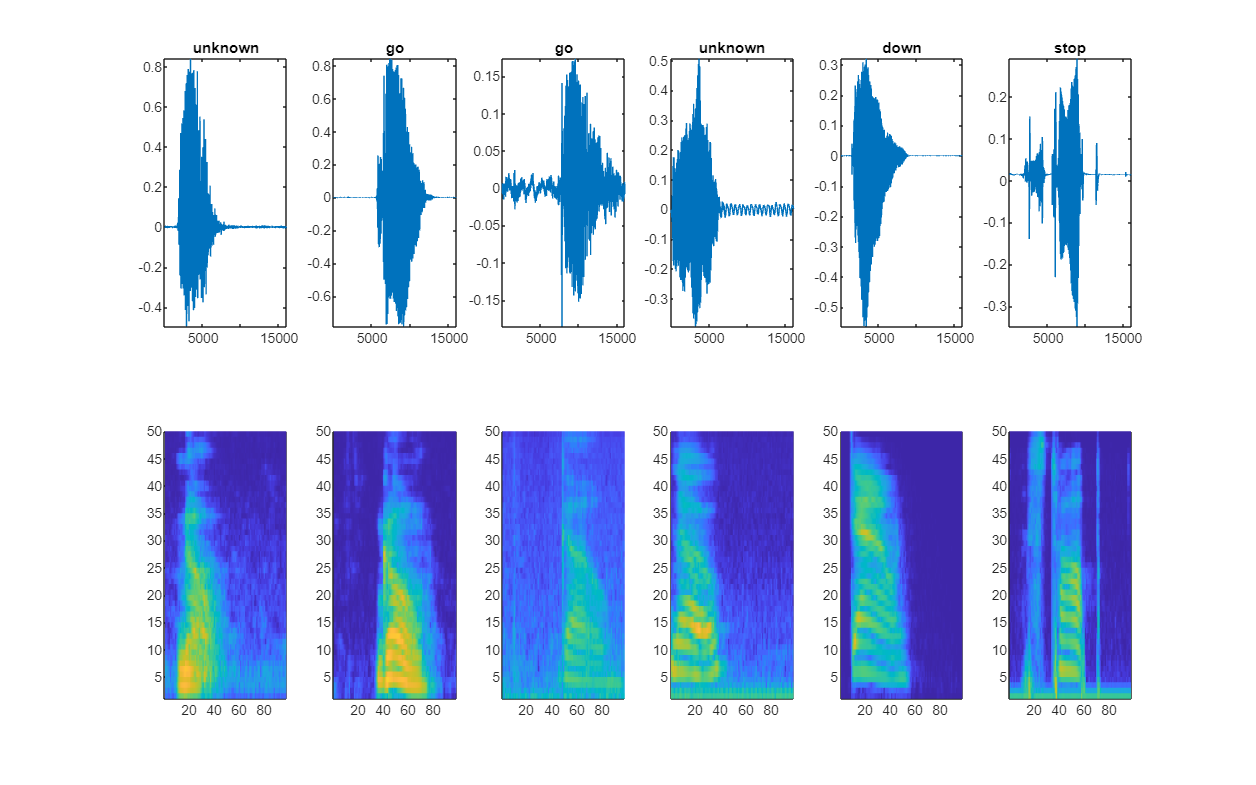

specMin = min(XTrain,[],"all");
specMax = max(XTrain,[],"all");
idx = randperm(numel(adsTrain.Files),6);
figure(Units="normalized",Position=[0.2 0.2 0.6 0.6]);
for ii = 1:6
    [x,fs] = audioread(adsTrain.Files{idx(ii)});

    subplot(2,6,ii)
    plot(x)
    axis tight
    title(string(adsTrain.Labels(idx(ii))))
    
    subplot(2,6,ii+6)
    spect = XTrain(:,:,1,idx(ii))';
    pcolor(spect)
    caxis([specMin specMax])
    shading flat
end

## Add Background Noise Data

The network must be able not only to recognize different spoken words but also to detect if the input contains silence or background noise.

adsBkg = audioDatastore(fullfile(dataset,"background"))

adsBkg =   audioDatastore with properties:

                       Files: {
                              '/tmp/google_speech/background/doing_the_dishes.wav';
                              '/tmp/google_speech/background/dude_miaowing.wav';
                              '/tmp/google_speech/background/exercise_bike.wav'
                               ... and 3 more
                              }
                     Folders: {
                              '/tmp/google_speech/background'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


numBkgClips = 4000;
volumeRange = log10([1e-4,1]);

numBkgFiles = numel(adsBkg.Files);
numClipsPerFile = histcounts(1:numBkgClips,linspace(1,numBkgClips,numBkgFiles+1));
Xbkg = zeros(size(XTrain,1),size(XTrain,2),1,numBkgClips,"single");
bkgAll = readall(adsBkg);
ind = 1;

for count = 1:numBkgFiles
    bkg = bkgAll{count};
    idxStart = randi(numel(bkg)-fs,numClipsPerFile(count),1);
    idxEnd = idxStart+fs-1;
    gain = 10.^((volumeRange(2)-volumeRange(1))*rand(numClipsPerFile(count),1) + volumeRange(1));
    for j = 1:numClipsPerFile(count)
        
        x = bkg(idxStart(j):idxEnd(j))*gain(j);
        
        x = max(min(x,1),-1);
        
        Xbkg(:,:,:,ind) = extract(afe,x);
        
        if mod(ind,1000)==0
            progress = "Processed " + string(ind) + " background clips out of " + string(numBkgClips)
        end
        ind = ind + 1;
    end
end

progress = "Processed 1000 background clips out of 4000"

progress = "Processed 2000 background clips out of 4000"

progress = "Processed 3000 background clips out of 4000"

progress = "Processed 4000 background clips out of 4000"

Xbkg = log10(Xbkg + epsil);

numTrainBkg = floor(0.85*numBkgClips);
numValidationBkg = floor(0.15*numBkgClips);

XTrain(:,:,:,end+1:end+numTrainBkg) = Xbkg(:,:,:,1:numTrainBkg);
TTrain(end+1:end+numTrainBkg) = "background";

XValidation(:,:,:,end+1:end+numValidationBkg) = Xbkg(:,:,:,numTrainBkg+1:end);
TValidation(end+1:end+numValidationBkg) = "background";

Plot the distribution of the different class labels in the training and validation sets.

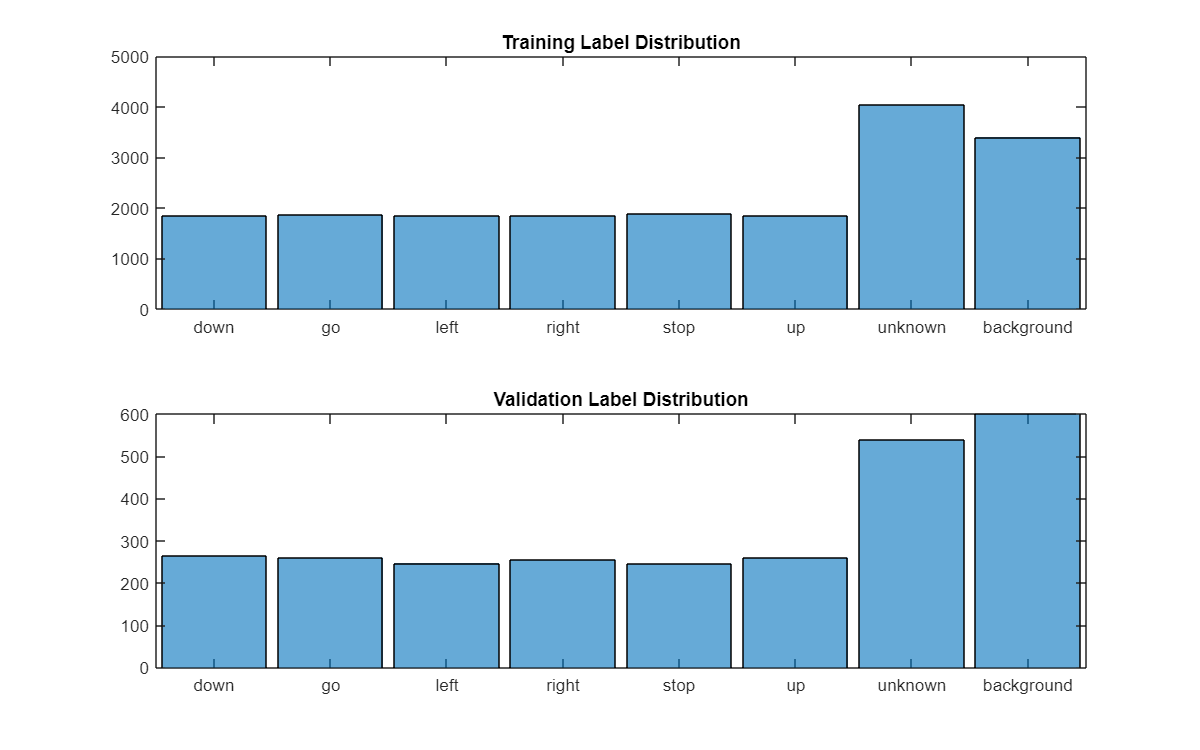

figure(Units="normalized",Position=[0.2 0.2 0.5 0.5])

tiledlayout(2,1)

nexttile
histogram(TTrain)
title("Training Label Distribution")

nexttile
histogram(TValidation)
title("Validation Label Distribution")

## Define Neural Network Architecture

classes = categories(TTrain);
classWeights = 1./countcats(TTrain);
classWeights = classWeights'/mean(classWeights);
numClasses = numel(categories(TTrain));
timePoolSize = ceil(numHops/8);
dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer([numHops numBands])
    
    convolution2dLayer(3,numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,Stride=2,Padding="same")
    
    convolution2dLayer(3,2*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,Stride=2,Padding="same")
    
    convolution2dLayer(3,4*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,Stride=2,Padding="same")
    
    convolution2dLayer(3,4*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,4*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([timePoolSize,1])
    
    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer(Classes=classes,ClassWeights=classWeights)];

## Train Network

miniBatchSize = 128;
validationFrequency = floor(numel(TTrain)/miniBatchSize);
options = trainingOptions("adam", ...
    InitialLearnRate=3e-3, ...
    MaxEpochs=10, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationData={XValidation,TValidation}, ...
    ValidationFrequency=validationFrequency, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=20);

trainedNet = trainNetwork(XTrain,TTrain,layers,options);

## Evaluate Trained Network

YValPred = classify(trainedNet,XValidation);
validationError = mean(YValPred ~= TValidation);
YTrainPred = classify(trainedNet,XTrain);
trainError = mean(YTrainPred ~= TTrain);

disp("Training error: " + trainError*100 + "%")

Training error: 2.4985%


disp("Validation error: " + validationError*100 + "%")

Validation error: 5.4266%


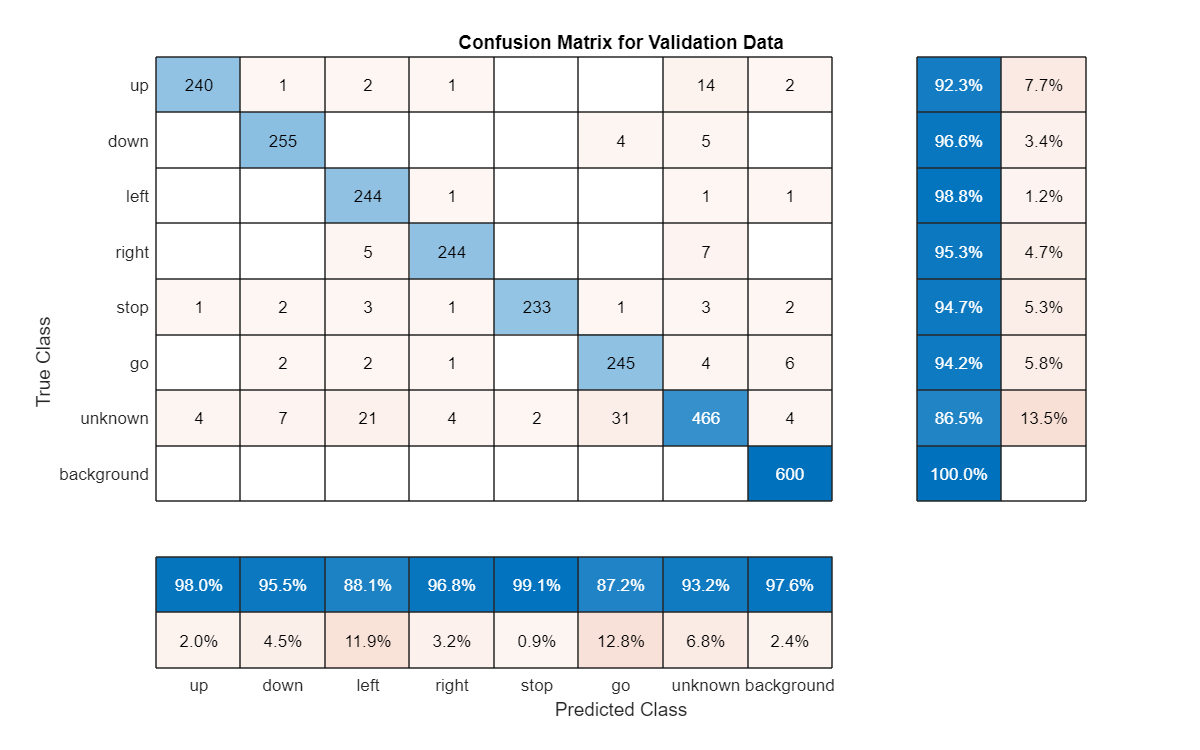

figure(Units="normalized",Position=[0.2 0.2 0.5 0.5]);
cm = confusionchart(TValidation,YValPred, ...
    Title="Confusion Matrix for Validation Data", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");
sortClasses(cm,[commands,"unknown","background"])

C=confusionmat(TValidation,YValPred)

C =    255     4     0     0     0     0     5     0
     2   245     2     1     0     0     4     6
     0     0   244     1     0     0     1     1
     0     0     5   244     0     0     7     0
     2     1     3     1   233     1     3     2
     1     0     2     1     0   240    14     2
     7    31    21     4     2     4   466     4
     0     0     0     0     0     0     0   600


precision = diag(C)./sum(C,2)

precision =     0.9659
    0.9423
    0.9879
    0.9531
    0.9472
    0.9231
    0.8646
    1.0000


recall = diag(C)./sum(C,1)'

recall =     0.9551
    0.8719
    0.8809
    0.9683
    0.9915
    0.9796
    0.9320
    0.9756


f1Scores = 2*(precision.*recall)./(precision+recall)

f1Scores =     0.9605
    0.9057
    0.9313
    0.9606
    0.9688
    0.9505
    0.8970
    0.9877


meanPrecision = mean(precision)

meanPrecision = 0.9480

meanRecall = mean(recall)

meanRecall = 0.9443

meanF1 = mean(f1Scores)

meanF1 = 0.9453

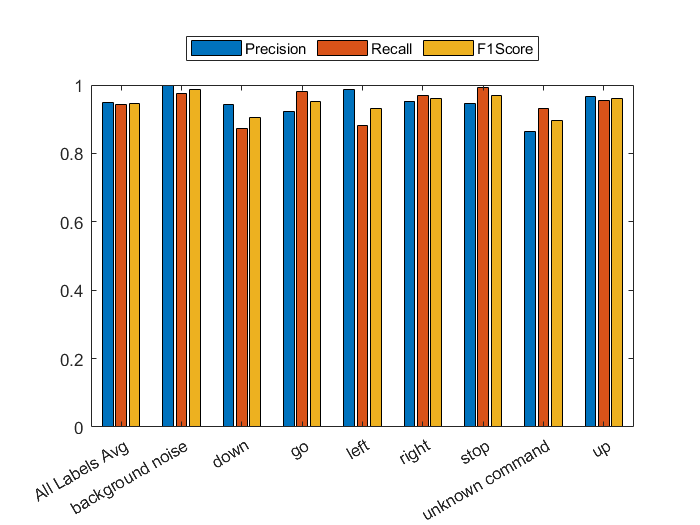

x=categorical({'up' 'down' 'left' 'right' 'stop' 'go' 'unknown command' 'background noise' 'All Labels Avg'});
y = [[precision meanPrecision],[recall meanRecall],[f1Scores meanF1]];
h = bar(x,y);
set(h, {'DisplayName'}, {'Precision', 'Recall', 'F1Score'}')
ylim([0 1])
legend('Orientation','horizontal', 'Location', 'northoutside') 